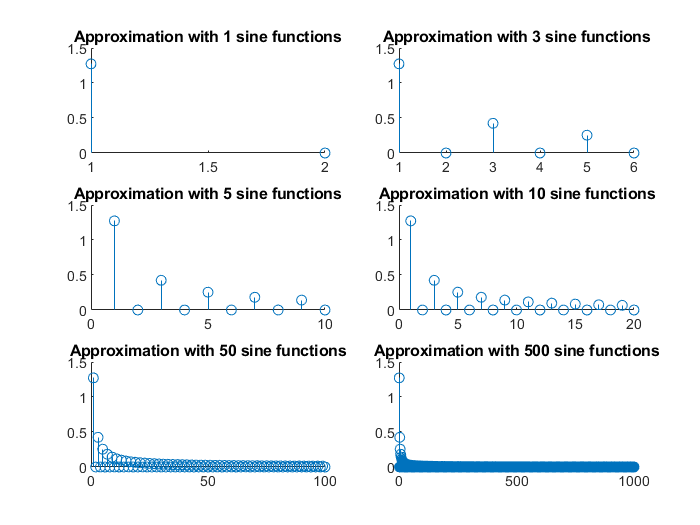

number = 1;
for n=[1,3,5,10,50,500]
    subplot(3,2,number);
    y = zeros(1,2*n);
    for x = 1:2:2*n-1
        y(:,x) = (4/pi) * (1/x);
    end
    x = 1:2*n;
    hold on;
    stem(x,y);
    hold off;
    number = number + 1;
    if (n==1 || n==3)
        axis ([1 2*n 0 1.5]);
    else
        axis ([0 2*n 0 1.5]);
    end
    title(['Approximation with ', num2str(n),' sine functions']);
end